# Proyecto Final - Reconocimiento de imágenes utilizando redes neuronales artificiales

Obtiene todas las imágenes de cada clase del directorio *Objetos_segmentados*

[imageClasses,labelMap] = ImageProcessing.getImagesClasses("Objetos_segmentados");

Se muestra la imagen 3 de la segunda clase

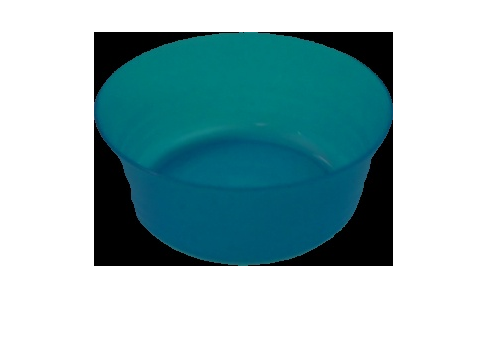

imshow(imageClasses{2}{3})

Se muestran las propiedades de labelMap y un ejemplo de su uso

labelMap

labelMap =   Map with properties:

        Count: 10
      KeyType: double
    ValueType: char


fprintf('A la clase %d le pertence la etiqueta %s',1,labelMap(1));

A la clase 1 le pertence la etiqueta appleJuice

Las redes neuronales trabajan entradas de igual tamaño. Esto implica que se debe estandarizar el tamaño de todas las imágenes. Para el caso de este proyecto se estandarizan a 200 x 200 pixeles

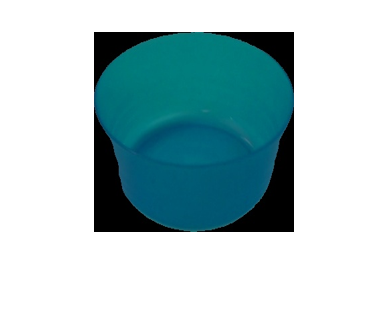

standarizedImages = ImageProcessing.standarizeImgSizes(imgs,200,200);
imshow(standarizedImages{2}{3})

Divide a las imágenes en datos de entreneamiento y datos de prueba

images_train = cellfun(@(imageClass) imageClass(1:15), standarizedImages, 'UniformOutput', false);
images_test = cellfun(@(imageClass) imageClass(16:end), standarizedImages, 'UniformOutput', false);

Transforma a las imágenes a vectores de una sola columna y los agrupa para generar los datos de entrada de la red neuronal.

input_data = ImageProcessing.imageInputs(images_train)

input_data =      0     3     0     0     0     0     0     0     0     0     0     0     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     3     0     0     0     0     0     1     0     0     1     1     1     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     3     0     0     0     1     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     1     0
     0     1     0     0     0     0     0     0     0     1     0     1     0     0

De forma similar genera una matriz para representar las clases objetivo.

output_data = ImageProcessing.imageOutputs(images_train)

output_data =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     

Se procede a crear una red neuronal feed forward  de una sóla capa oculta de tamaño 10.

net = patternnet(10);

La red neuronal es entrenada.

trainedNet = train(net,input_data,output_data)

trainedNet =

    Neural Network
 
              name: 'Pattern Recognition Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 1200120
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      

Se visualiza el diagrama de la red neuronal

% Es necesario correr esta sección para mostrar el diagrama
view(trainedNet)

Clasificación de las imagenes de entrenamiento

disp('Clasificación de las imágenes de entrenamiento')

Clasificación de las imágenes de entrenamiento


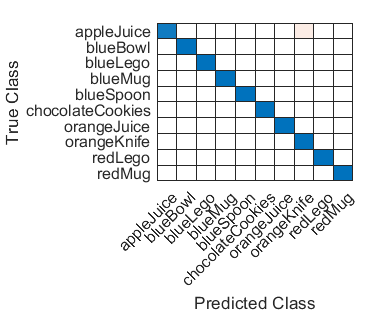

clasificacionRedNeuronal(trainedNet,input_data,output_data,labelMap)

Clasificación de las imagenes de prueba

disp('Clasificación de las imágenes de prueba')

Clasificación de las imágenes de prueba


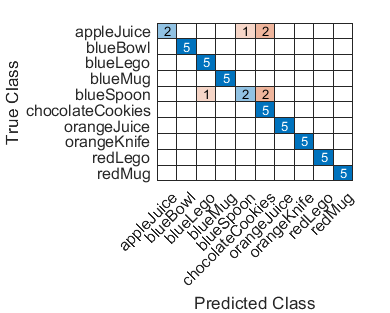

input_test = ImageProcessing.imageInputs(images_test);
output_test = ImageProcessing.imageOutputs(images_test);
clasificacionRedNeuronal(trainedNet,input_test,output_test,labelMap)

**Clasificación de imágenes usando la red neuronal**

Función para clasificar las imagenes, ya sea de entrenamiento o de prueba mediante la tecnica de redes neuronales.

x son los datos de entrada

y son los datos de salida esperados para los datos de entrada x

Al final muestra su matriz de confusión.

function clasificacionRedNeuronal(trainedNet,x,y,labelMap)
    % Aplica los vectores de entrada a la función estimada por la red neuronal
    y_train = trainedNet(x);
    % Obtiene la clasificación de acuerdo a la predicción realizada por la red
    % neruonal
    y_train_predicted = vec2ind(y_train);
    % Obtiene la clasificación esperada
    y_train_expected = vec2ind(y);
    % Transforma las predicciones a su etiqueta correspondiente
    y_train_pr_label = arrayfun(@(num) labelMap(num),y_train_predicted,'UniformOutput',false);
    % Transforma las clasificaciones a su etiqueta correspondiente
    y_train_ex_label = arrayfun(@(num) labelMap(num),y_train_expected,'UniformOutput',false);
    confusionchart(y_train_ex_label,y_train_pr_label)
end